# Some examples for the application of remezex()

Execution date

datetime("today")

ans = datetime
   01-Jan-2024


## Example 1: exp()

*** Start of iteration 1 ***
Polynomial coefficients: 
0.500244, 1, 1
Error: 4.8208e-12
Error function root #1 in interval [0, 0.00022617]: 6.5007e-05
Error function root #2 in interval [0.00022617, 0.00075401]: 0.00048788
Error function root #3 in interval [0.00075401, 0.00097656]: 0.00091167
Extremum #1 in interval [0, 6.5007e-05] at 0 with error 4.8208e-12
Extremum #2 in interval [6.5007e-05, 0.00048788] at 0.00024378 with error 4.8597e-12
Extremum #3 in interval [0.00048788, 0.00091167] at 0.0007326 with error 4.8785e-12
Extremum #4 in interval [0.00091167, 0.00097656] at 0.00097656 with error 4.8208e-12
Node with largest error e(0.00075401) = 4.8785e-12
Shifting all points by:
0, 1.76101e-05, -2.14055e-05, 0


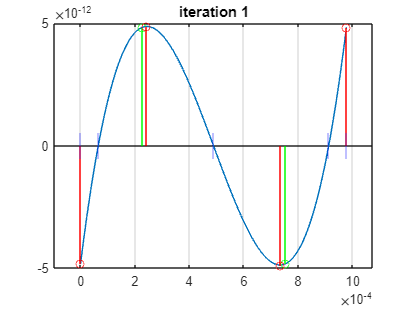

*** Start of iteration 2 ***
Polynomial coefficients: 
0.500244, 1, 1
Error: 4.8529e-12
Error function root #1 in interval [0, 0.00024378]: 6.5423e-05
Error function root #2 in interval [0.00024378, 0.0007326]: 0.00048831
Error function root #3 in interval [0.0007326, 0.00097656]: 0.00091115
Extremum #1 in interval [0, 6.5423e-05] at 0 with error 4.853e-12
Extremum #2 in interval [6.5423e-05, 0.00048831] at 0.00024416 with error 4.853e-12
Extremum #3 in interval [0.00048831, 0.00091115] at 0.00073244 with error 4.853e-12
Extremum #4 in interval [0.00091115, 0.00097656] at 0.00097656 with error 4.853e-12
Node with largest error e(0) = 4.853e-12
Largest position shift 0 below threshold 9.3132e-10 --> exiting
Best approximation polynomial of order 2 over [0, 0.00097656] with max abs error 4.8529e-12:
+5.002442128293296e-01 * x^2
+9.999999105563995e-01 * x^1
+1.000000000004853e+00


fun_str  = "exp()";
fun      = @(x) exp(x);
fun_der  = @(x) exp(x);
interval = [0, 2^(-10)];
order    = 2;
[p, ~] = remezex(fun, fun_der, interval, order, 'multi', true, 'verbosity', 3);

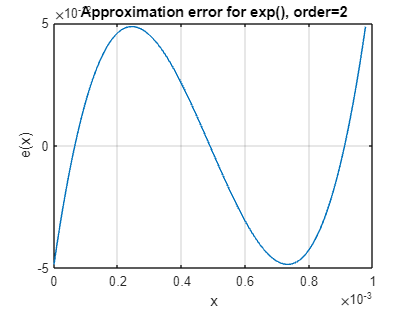

plot_demo(fun, fun_str, p, interval);

## Example 2: exp()

interval = [-8 0];
order    = 5;
[p, ~] = remezex(fun, fun_der, interval, order, 'multi', true, 'verbosity', 2);

*** Start of iteration 1 ***
Polynomial coefficients: 
0.000310159, 0.00784691, 0.0773789, 0.376828, 0.934537, 0.99457
Error: 0.0054302
Error function root #1 in interval [-8, -7.4152]: -7.8465
Error function root #2 in interval [-7.4152, -5.978]: -6.7092
Error function root #3 in interval [-5.978, -4.1761]: -4.8391
Error function root #4 in interval [-4.1761, -2.0777]: -2.639
Error function root #5 in interval [-2.0777, -0.55164]: -0.94456
Error function root #6 in interval [-0.55164, 0]: -0.10068
Extremum #1 in interval [-8, -7.8465] at -8 with error 0.0054302
Extremum #2 in interval [-7.8465, -6.7092] at -7.4009 with error 0.0054343
Extremum #3 in interval [-6.7092, -4.8391] at -5.8156 with error 0.0056333
Extremum #4 in interval [-4.8391, -2.639] at -3.6997 with error 0.0069214
Extremum #5 in interval [-2.639, -0.94456] at -1.7111 with error 0.0068232
Extremum #6 in interval [-0.94456, -0.10068] at -0.42458 with error 0.0059981
Extremum #7 in interval [-0.10068, 0] at 0 with error 

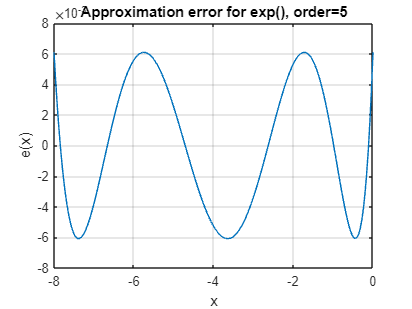

plot_demo(fun, fun_str, p, interval);

## Example 3: sin()

fun_str  = "sin()";
fun      = @(x) sin(x);
fun_der  = @(x) cos(x);
interval = [0, 2^(-10)];
order    = 2;
[p, ~] = remezex(fun, fun_der, interval, order, 'verbosity', 1);

*** Start of iteration 1 ***
Shifting x(3)=0.00070876 by 2.3737e-05
*** Start of iteration 2 ***
Shifting x(2)=0.00025982 by -1.5602e-05
*** Start of iteration 3 ***
Shifting x(2)=0.00024422 by -8.1338e-08
*** Start of iteration 4 ***
Shifting x(3)=0.0007325 by -7.5053e-08
*** Start of iteration 5 ***
Best approximation polynomial of order 2 over [0, 0.00097656] with max abs error 4.8506e-12:
-2.441406091975296e-04 * x^2
+1.000000089406958e+00 * x^1
-4.850637729231143e-12


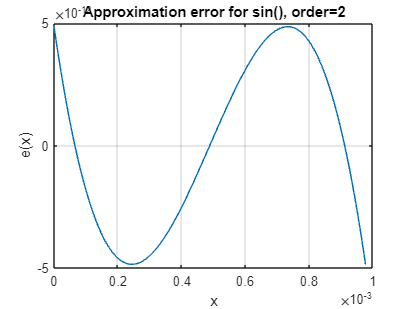

plot_demo(fun, fun_str, p, interval);

## Example 4: sin()

interval = [-8 0];
order    = 5;
[p, ~] = remezex(fun, fun_der, interval, order, 'verbosity', 1);

*** Start of iteration 1 ***
Shifting x(5)=-1.9321 by -0.39714
*** Start of iteration 2 ***
Shifting x(4)=-3.9404 by -0.34852
*** Start of iteration 3 ***
Shifting x(6)=-0.52006 by -0.19238
*** Start of iteration 4 ***
Shifting x(2)=-7.5131 by 0.029377
*** Start of iteration 5 ***
Shifting x(3)=-6.0969 by -0.020044
*** Start of iteration 6 ***
Shifting x(5)=-2.3293 by -0.014157
*** Start of iteration 7 ***
Shifting x(4)=-4.2889 by 0.0092874
*** Start of iteration 8 ***
Shifting x(6)=-0.71244 by 0.0040237
*** Start of iteration 9 ***
Shifting x(2)=-7.4837 by -0.00011679
*** Start of iteration 10 ***
Shifting x(3)=-6.117 by 2.8287e-05
*** Start of iteration 11 ***
Shifting x(5)=-2.3434 by -6.8718e-06
*** Start of iteration 12 ***
Shifting x(4)=-4.2796 by 4.3516e-06
*** Start of iteration 13 ***
Shifting x(6)=-0.70842 by 1.6481e-06
*** Start of iteration 14 ***
Shifting x(2)=-7.4838 by -2.5851e-09
*** Start of iteration 15 ***
Best approximation polynomial of order 5 over [-8, 0] with max

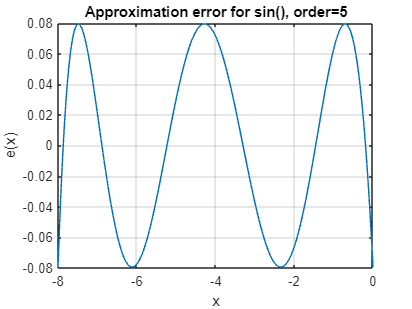

plot_demo(fun, fun_str, p, interval);

## Example 5: atan()

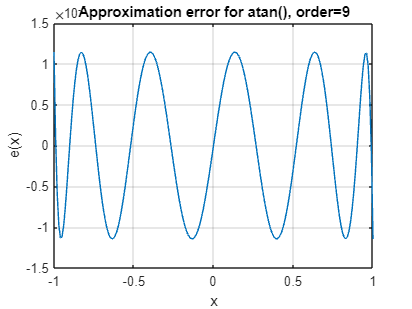

fun_str  = "atan()";
fun      = @(x) atan(x);
fun_der  = @(x) 1./(x.^2+1);
interval = [-1 1];
order    = 9;
[p, ~] = remezex(fun, fun_der, interval, order);
plot_demo(fun, fun_str, p, interval);

## Helper function

function plot_demo(fun, fun_str, p, interval)
    % plotting the error of the whole interval
    numTestPoints = 200;
    x = linspace(interval(1), interval(2), numTestPoints);
    e = fun(x) - polyval(p, x);
    figure();
    plot(x, e);
    xlabel('x'); ylabel('e(x)'); grid on;
    order = numel(p)-1;
    title("Approximation error for " + fun_str + ", order=" + order);
end